# **CP241 - Lab Assignment 3**

**Note: **Write your answers in the dedicated section only and submit this file as per instructions provided in the question paper.

**QUESTION-1(a) **

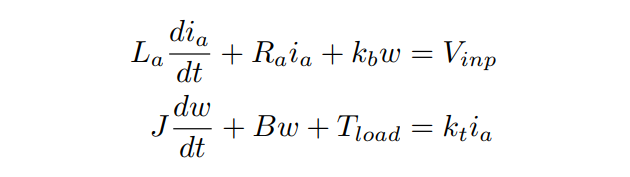

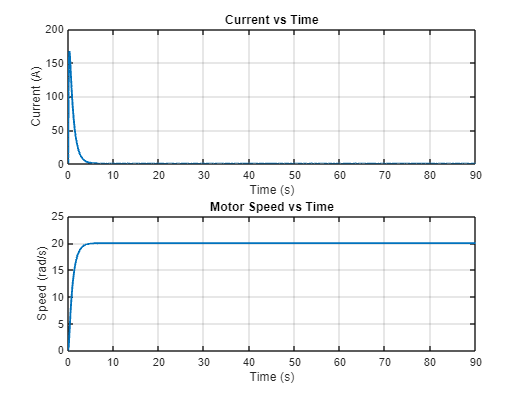

% Motor parameters
Ra = 0.1;   
La = 0.01;  
J = 10;     
B = 0.01;    
kb = 1;     
kt = 1;    

V_in = 20;
Torq = 0;  

%motor function
motorODE = @(t, y) [
    (V_in - Ra*y(1) - kb*y(2))/La,...  
    (kt*y(1) - B*y(2) - Torq)/J ]';   

tspan = [0 90];
y0 = [0, 0]'; % Initial conditions

% ODE45
[t, y] = ode45(motorODE, tspan, y0);
% disp(y(1));
% disp(y(2));

%current
subplot(2,1,1);
plot(t, y(:,1), 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Current (A)');
title('Current vs Time');
grid on;

% speed
subplot(2,1,2);
plot(t, y(:,2), 'LineWidth', 1.5);
ylim([0,25]);
xlabel('Time (s)');
ylabel('Speed (rad/s)');
title('Motor Speed vs Time');
grid on;

**QUESTION-1(b)**

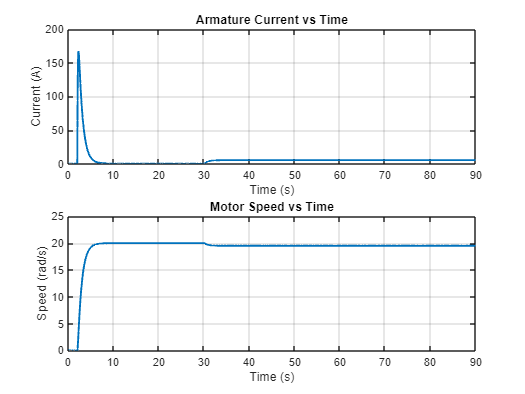

% Time-dependent input voltage and load torque
Vinp = @(t) (t >= 2) * 20;   % 20V step at t=2s
Tload = @(t) (t >= 30) * 5;  % 5Nm step at t=30s

motorODE = @(t, y) [
    (Vinp(t) - Ra*y(1) - kb*y(2))/La,...
    (kt*y(1) - B*y(2) - Tload(t))/J    
]';

tspan = [0 90];  
y0 = [0; 0]; 

% DE45
[t, y] = ode45(motorODE, tspan, y0);

% Plot current
subplot(2,1,1);
plot(t, y(:,1), 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Current (A)');
title('Armature Current vs Time');
grid on;

% Plot speed
subplot(2,1,2);
plot(t, y(:,2), 'LineWidth', 1.5);
ylim([0,25]);
xlabel('Time (s)');
ylabel('Speed (rad/s)');
title('Motor Speed vs Time');
grid on;

**QUESTION-1(c) **

syms x_1 x_2;

f1 = (-Ra*x_1 - kb*x_2)/La; %equation1
f2 = (kt*x_1 - B*x_2)/J; %equation2

Jacob = jacobian([f1, f2], [x_1, x_2]);
equ_Points = vpasolve([f1 == 0, f2 == 0], [x_1, x_2]);

J_equilibrium = double(subs(Jacob, [x_1, x_2], [equ_Points.x_1, equ_Points.x_2]));

e_values = eig(J_equilibrium); %Eigen values
disp('Equilibrium Points are :');

Equilibrium Points are :


disp(equ_Points);

    x_1: 0
    x_2: 0



disp('Eigenvalues at Equilibrium :');

Eigenvalues at Equilibrium :


fprintf('lambda1= %.2f\n ', e_values(1));

lambda1= -8.87
 

fprintf('lambda2= %.2f\n ', e_values(2));

lambda2= -1.13
 

**equilibrium points are : 0 and 0**

**The eigen values are : -8.87 and -1.13**

**QUESTION-1(d) **

**:-Both Eigen values are Real and Negative ,Phase potrait Represents Stable node Equlibrium point**

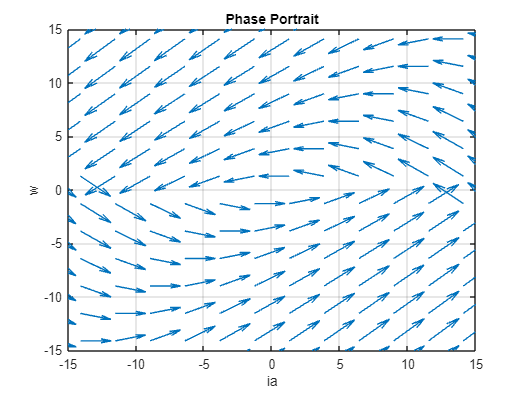

x1_lim = [-50, 50];
x2_lim = [-50; 50];
step_size = 40;

figure;
[x1, x2] = meshgrid(linspace(x1_lim(1), x1_lim(2), step_size), ...
                                linspace(x2_lim(1), x2_lim(2), step_size));
U = (-1 * Ra/La) * x1 + (-1 * kb/La) * x2;
V = (kt/J)*x1 - (1/J)*x2;
U = U./sqrt(U.^2 + V.^2);
V = V./sqrt(U.^2 + V.^2);
quiver(x1, x2, U, V);
xlabel('ia');
ylabel('w');
title('Phase Portrait')
grid on
xlim([-15.0 15.0])
ylim([-15.0 15.0])

**QUESTION-2(a) **

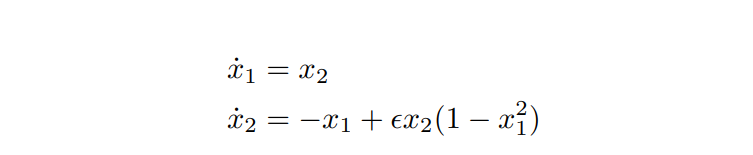

**case1: epsilon=0**

***Phase portrait  type : Center**

clc;
clear all;
close all;

%Epsilon = 0
%x_1 and x_2 are two equlibrium points
syms x_1 x_2
eqn1 = x_2 == 0;
eqn2 = -x_1 == 0;
equilibriumPoints = solve([eqn1, eqn2], [x_1, x_2]);
disp('Equilibrium points:')

Equilibrium points:


disp(['x_1 = ', num2str(double(equilibriumPoints.x_1))]);

x_1 = 0


disp(['x_2 = ', num2str(double(equilibriumPoints.x_2))]);

x_2 = 0


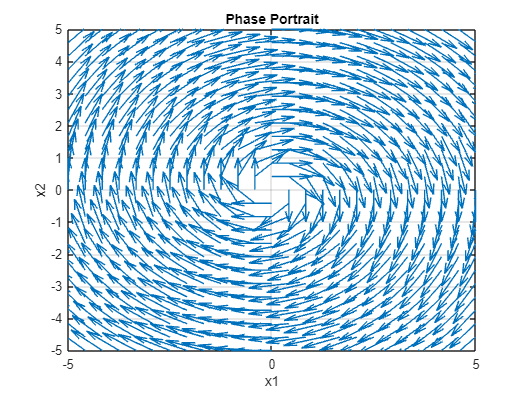

x1_lim = [-5.0, 5.0];
x2_lim = [-5.0; 5.0];
step_size = 25;
[x1, x2] = meshgrid(linspace(x1_lim(1), x1_lim(2), step_size), ...
                                linspace(x2_lim(1), x2_lim(2), step_size));
U = x2;
V = -1 * x1;
arrowLength =sqrt(U.^2 + V.^2);
U = U./arrowLength;
V = V./arrowLength;

figure;
quiver(x1, x2, U, V,'AutoScale', 'off');
xlabel('x1');
ylabel('x2');
title('Phase Portrait')
grid on
xlim([-5.0 5.0])
ylim([-5.0 5.0])

**QUESTION-2(a) **

**case2:epsilon=1**

***Phase portrait  type : Stable focus**

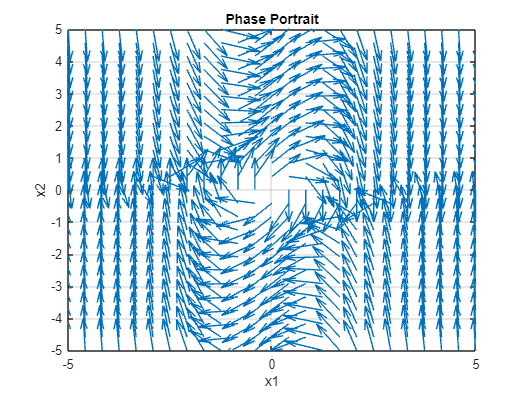

x1_lim = [-5.0, 5.0];
x2_lim = [-5.0; 5.0];
step_size = 25;
[x1, x2] = meshgrid(linspace(x1_lim(1), x1_lim(2), step_size), ...
                                linspace(x2_lim(1), x2_lim(2), step_size));
U = x2;
V = zeros(size(x1));
for i=1:size(x1, 1)
    for j = 1:size(x1, 2)
        temp = -x1(i,j) + x2(i,j)*(1 - x1(i,j)^2);
        V(i,j) = temp;
    end
end
arrowLength = sqrt(U.^2 + V.^2);
U = U./arrowLength;
V = V./arrowLength;

figure;
quiver(x1, x2, U, V,'AutoScale', 'off');
xlabel('x1');
ylabel('x2');
title('Phase Portrait')
grid on
xlim([-5.0 5.0])
ylim([-5.0 5.0])

**QUESTION-2(b) **

**case1: epsilon=0 :**

**> **

***Linear homogeneous system**

***Equlibrium points(0,0) are at the center**

***Trajectories moving around the center**

***System shows periodic orbit for each initial conditon,system will not escape or not  move towards the equlibrium points**

***Solution will neither converge nor divarg,it will always spins across equlibrium points**

**case2: epsilon=1 :**

**>**

***Non linear system**

***Equlibrium points(0,0) **

***Stable focus**

***Trajectories are  spiral towards the equilibrium point over time**

***System shows osillatory behaviour and solution will appear over time**

***The system is stable around the equilibrium point**

**QUESTION-2(c) epsilon=0**

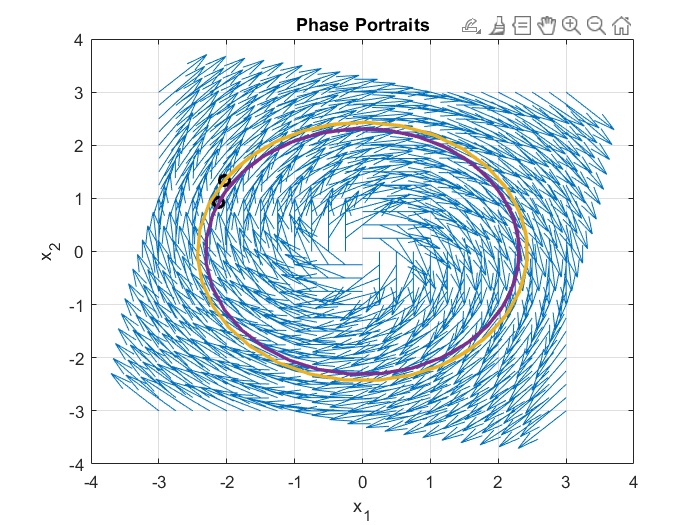

eps = 0; %epsilon

f = @(t, y) [y(2); -y(1) + eps*y(2)*(1 - y(1)^2)];

% mesh for start trejectory
[x1, x2] = meshgrid(-3:0.25:3, -3:0.25:3);

u = x2;
v = -x1 + eps*x2.*(1 - x1.^2);
arrowLength = sqrt(u.^2 + v.^2);
u = u ./ arrowLength;
v = v ./ arrowLength;

figure;
quiver(x1, x2, u, v, 'AutoScale', 'off');

hold on;
xlabel('x_1');
ylabel('x_2');
title('Phase Portraits');
grid on;
[x0, y0] = ginput(2);

% Plot initial conditions
plot(x0, y0, 'ko', 'LineWidth', 2);

for k = 1:length(x0)
    [~, traj] = ode45(f, [0, 10], [x0(k); y0(k)]);
    plot(traj(:, 1), traj(:, 2), 'LineWidth', 2);
end

hold off;

**QUESTION-2(c) epsilon=1**

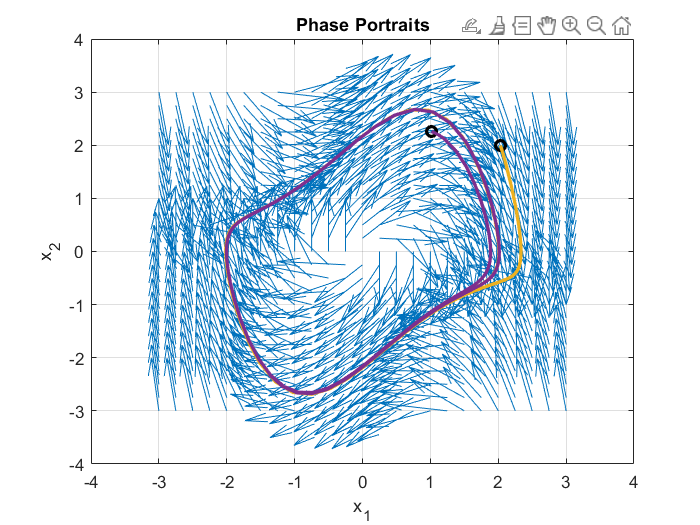


eps = 1;

f = @(t, y) [y(2); -y(1) + eps*y(2)*(1 - y(1)^2)];
[x1, x2] = meshgrid(-3:0.25:3, -3:0.25:3);
u = x2;
v = -x1 + eps*x2.*(1 - x1.^2);

arrowLength = sqrt(u.^2 + v.^2);
u = u ./ arrowLength;
v = v ./ arrowLength;

figure;
quiver(x1, x2, u, v, 'AutoScale', 'off');

hold on;
xlabel('x_1');
ylabel('x_2');
title('Phase Portraits');
grid on;

[x0, y0] = ginput(2);
plot(x0, y0, 'ko', 'LineWidth', 2);

for k = 1:length(x0)
    [~, traj] = ode45(f, [0, 10], [x0(k); y0(k)]);
    plot(traj(:, 1), traj(:, 2), 'LineWidth', 2);
end

hold off;

**QUESTION-3**

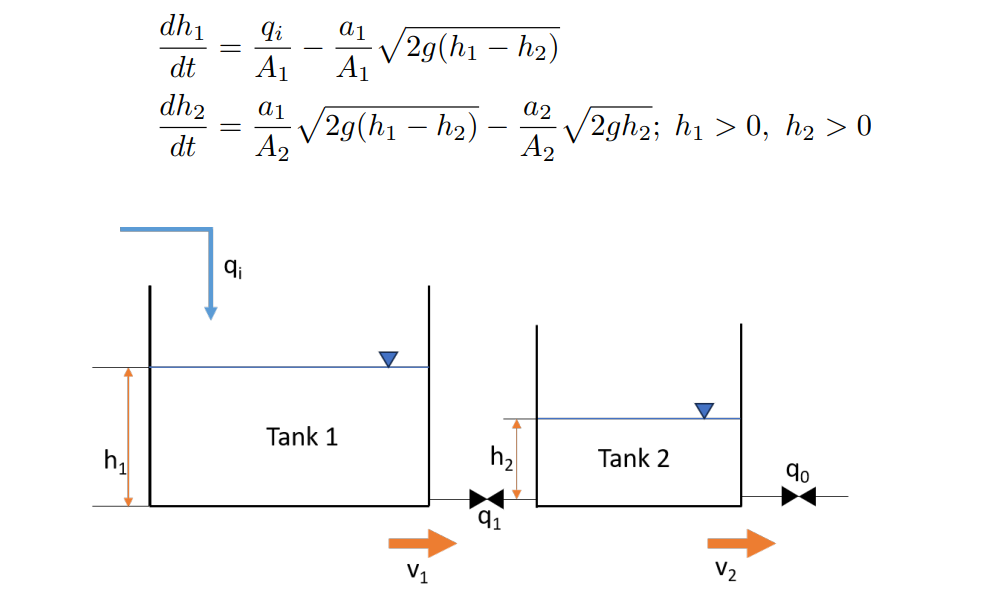

**QUESTION-3(a)**

clc;
clear all;
close all;

%Data given
a1 = 2e-3; 
a2 = 2e-3; 
A1 = 0.25; 
A2 = 0.10; 
g = 9.8; 
qi = 15e-3;

x1_lim = [-5.0, 5.0];
x2_lim = [-5.0, 5.0];
step_size = 15;

[x1, x2] = meshgrid(linspace(x1_lim(1), x1_lim(2), step_size), ...
                                linspace(x2_lim(1), x2_lim(2), step_size));
U = zeros(size(x1));
V = zeros(size(x2));


h_tank = @(t, X)[(qi/A1) - (a1/A1)*sqrt(2*g*(X(1) - X(2))); (a1/A2)*sqrt(2*g*(X(1) - X(2))) - (a2/A2)*sqrt(2*g*X(2))];

for i = 1:size(x1, 1)
    for j = 1: size(x1, 2)
        temp = h_tank(0, [x1(i, j); x2(i, j)]);
        U(i, j) = temp(1);
        V(i, j) = temp(2);
    end
end

U = U./sqrt(U.^2 + V.^2);
V = V./sqrt(U.^2 + V.^2);
quiver(x1, x2, U, V);

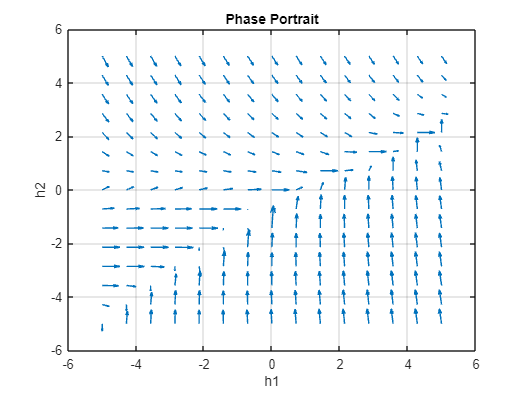

xlabel('h1');
ylabel('h2');
title('Phase Portrait')
grid on
xlim([-6.0 6.0])
ylim([-6.0 6.0])

**QUESTION-3(b)**

**Case 1: Stable : **

**Equlibrium point of the systems are (5.75, 2.88)**

**To check the stable case,From the give data Taking  initial guess value as , a1=a2= 2x10^-3**

***From the Phase portrait the we can observe the given system is approching towards the equlibrium point.**

***We can conclude for a1=a2= 2x10^-3  the system become stable stable**

clc;
close all;
clear all;

%given
a1 = 2e-3;
a2 = 2e-3;
A1 = 0.25;
A2 = 0.10;
g = 9.8;
qi = 15e-3;

x1_lim = [-10, 10];
x2_lim = [-10, 10];
step_size = 10;

[x1, x2] = meshgrid(linspace(x1_lim(1), x1_lim(2), step_size), ...
                                linspace(x2_lim(1), x2_lim(2), step_size));
U = zeros(size(x1));
V = zeros(size(x2));


h_tank = @(t, X)[(qi/A1) - (a1/A1)*sqrt(2*g*(X(1) - X(2))); (a1/A2)*sqrt(2*g*(X(1) - X(2))) - (a2/A2)*sqrt(2*g*X(2))];
for i = 1:size(x1, 1)
    for j = 1: size(x1, 2)
        temp = h_tank(0, [x1(i, j); x2(i, j)]);
        U(i, j) = temp(1);
        V(i, j) = temp(2);
    end
end

U = U./sqrt(U.^2 + V.^2);
V = V./sqrt(U.^2 + V.^2);
quiver(x1, x2, U, V, '-k');

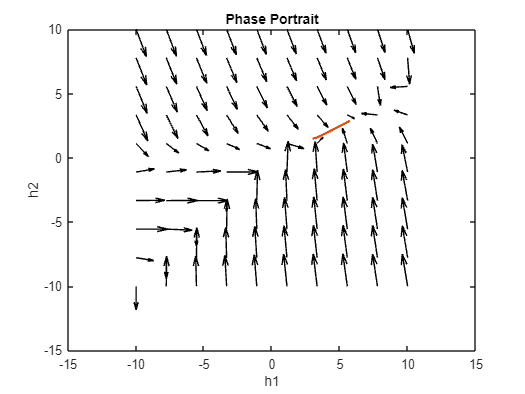

hold on;
params = [a1; a2; A1; A2; g; qi];
tspan = [0, 1000];
[t, X] = ode45(@(t, X) tank(X, params), tspan, [3; 1.5]);
plot(X(:, 1), X(:, 2), 'LineWidth',2);
xlabel('h1');
ylabel('h2');
title('Phase Portrait')
hold off;

**Case2:Unstable: for checking unstable case we have to itreate a system with a1 and a2 values from 2x10^-4 to 1**

***by keeping a1=2x10^-3 and  keep on varing the a2**

***After several itretaion we observed that whenver the a2 crosses 5x10^-4 the system shows unstable behaviour**

***The system is unstable when a1=a2>=5x10^-4 or one of them are greater**

clc;
clear all;

%given
a1 = 2e-3;
a2 = 5e-4; %checking unstable case
A1 = 0.25;
A2 = 0.10;
g = 9.8;
qi = 15e-3;

x1_lim = [-15, 15];
x2_lim = [-15, 15];
step_size = 10;
[x1, x2] = meshgrid(linspace(x1_lim(1), x1_lim(2), step_size), ...
                                linspace(x2_lim(1), x2_lim(2), step_size));
U = zeros(size(x1));
V = zeros(size(x2));


tank_height = @(t, X)[(qi/A1) - (a1/A1)*sqrt(2*g*(X(1) - X(2))); (a1/A2)*sqrt(2*g*(X(1) - X(2))) - (a2/A2)*sqrt(2*g*X(2))];
for i = 1:size(x1, 1)
    for j = 1: size(x1, 2)
        temp = tank_height(0, [x1(i, j); x2(i, j)]);
        U(i, j) = temp(1);
        V(i, j) = temp(2);
    end
end
U = U./sqrt(U.^2 + V.^2);
V = V./sqrt(U.^2 + V.^2);
quiver(x1, x2, U, V, '-k');

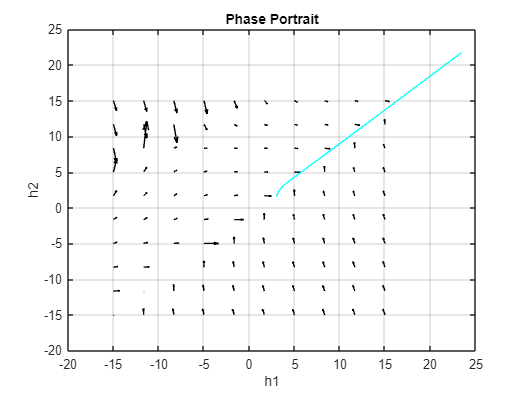

hold on;
params = [a1; a2; A1; A2; g; qi];
tspan = [0, 1000];
[t, X] = ode45(@(t, X) tank(X, params), tspan, [3; 1.5]);
plot(X(:, 1), X(:, 2), '-c');
xlabel('h1');
ylabel('h2');
title('Phase Portrait')
grid on;
hold off;

**FUNCTION DECLARATIONS(if needed has to be declared only at the end of the .mlx script)**

function heights = tank(X, params)
    heights = [0; 0];
    a1 = params(1); a2 = params(2); A1 = params(3); A2 = params(4); g = params(5); qi = params(6);
    heights(1) = (qi/A1) - (a1/A1)*sqrt(2*g*(X(1) - X(2)));
    heights(2) = (a1/A2)*sqrt(2*g*(X(1) - X(2))) - (a2/A2)*sqrt(2*g*X(2));
end